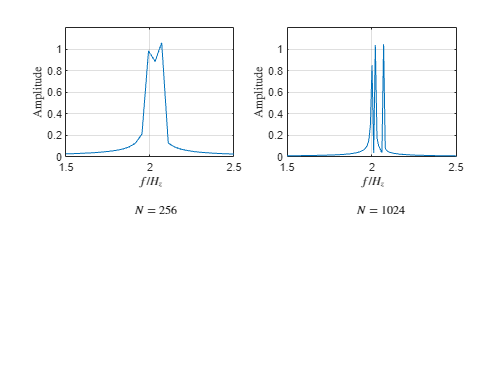

f1 = 2; f2 = 2.02; f3 = 2.07; fs = 10;
w=2*pi/fs;N= 256;n= 0: N-1;F= fs/N;
x=sin(w*f1*n)+ sin(w*f2 *n)+sin(w*f3*n);X= 2* dft(x,N)/N;
Y= abs(X); k= 0: N/2 -1;
f=k*F;
subplot(2,2,1);plot(f,Y(1: N/2)); xlabel('$f/H_z$',Interpreter='latex');ylabel('Amplitude',Interpreter='latex');text(1.9,-0.5,'$N=256$',Interpreter='latex')
axis([1.5 2.5 0 1.2]); grid on;
N= 1024;n=0:N-1;F= fs/N;
x=sin(w*f1*n)+sin(w*f2*n)+sin(w*f3*n);X= 2* dft(x,N)/N;
Y= abs(X); k=0: N/2-1;f=k*F;
subplot(222); plot(f,Y(1: N/2));xlabel('$f/H_z$',Interpreter='latex'); ylabel('Amplitude',Interpreter='latex');text(1.9,-0.5,'$N=1024$',Interpreter='latex')
axis([1.5 2.5 0 1.2]); grid on;